Script for comparison of visual/manual and algorithm scoring

- manual scoring is in seconds

- variable names for columns: ch1Start  ch1Stop 

make indexed vector of EEG signal where 1 = event (seizure) signal and 0 = normal signal for VISUAL scoring

fs = 500    

fs = 500

[vRow, ~] = size(visScores);
    visIdx = [];
    for i = 1:vRow
        vis = visScores(i,1):visScores(i,2);
        visIdx = [visIdx vis];
        clear vis
    end
    visIdx = visIdx';
    EEGLength = floor(length(EEG)/fs);
    visSeizures(:,1) = zeros(EEGLength,1);
    visSeizures(visIdx,1) = 1;
    %visSeizuresCat = categorical(visSeizures);
    clear vRow visIdx %visScores


Make indexed vector of EEG signal where 1 = event (seizure) signal and 0 = normal signal for ALGORITHM scoring

algIdx = [];
%algScores = resultsSumm(2,k).seizure;
[aRow, ~] = size(algScores);
for i = 1:aRow
    alg = floor(algScores(i,1)):floor(algScores(i,2));
    algIdx = [algIdx alg];
    clear alg
end
algIdx = algIdx';
algSeizures(:,1) = zeros(EEGLength,1);
algSeizures(algIdx,1) = 1;
%algSeizuresCat = categorical(algSeizures);
clear aRow algIdx %algScores


visSeizure = visSeizures(:,1);
algSeizure = algSeizures(:,1);
% for k = 2:CH
%     visSeizure = [visSeizure; visSeizures(:,1)];
%     algSeizure = [algSeizure; algSeizures(:,1)];
% end

Compute confusion matrix

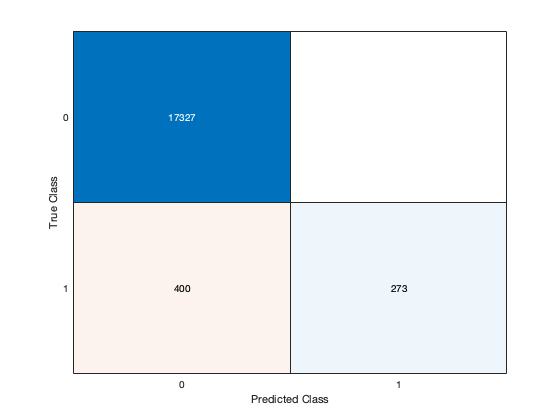

M =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


%[c,cm,ind,per] = confusion(visSeizures,algSeizures)
figure


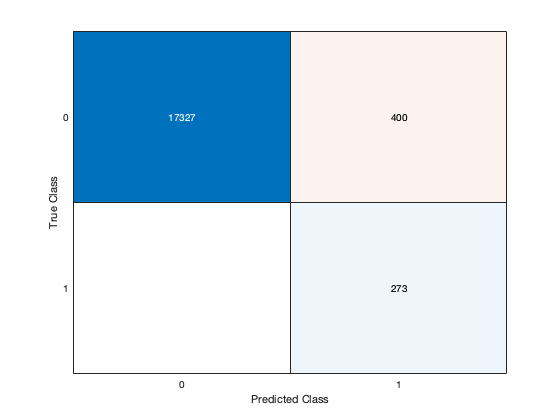

MM =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


M = confusionchart(algSeizure,visSeizure)

% name= char('+T11-070716')
% plotconfusion(visSeizuresCat,algSeizuresCat,name)

To plot comparisons